# DH Parameters

## Modified DH Parameters. 

Following the Book. Introduction to Robotics by John Craight

### Forward kinematics of a link

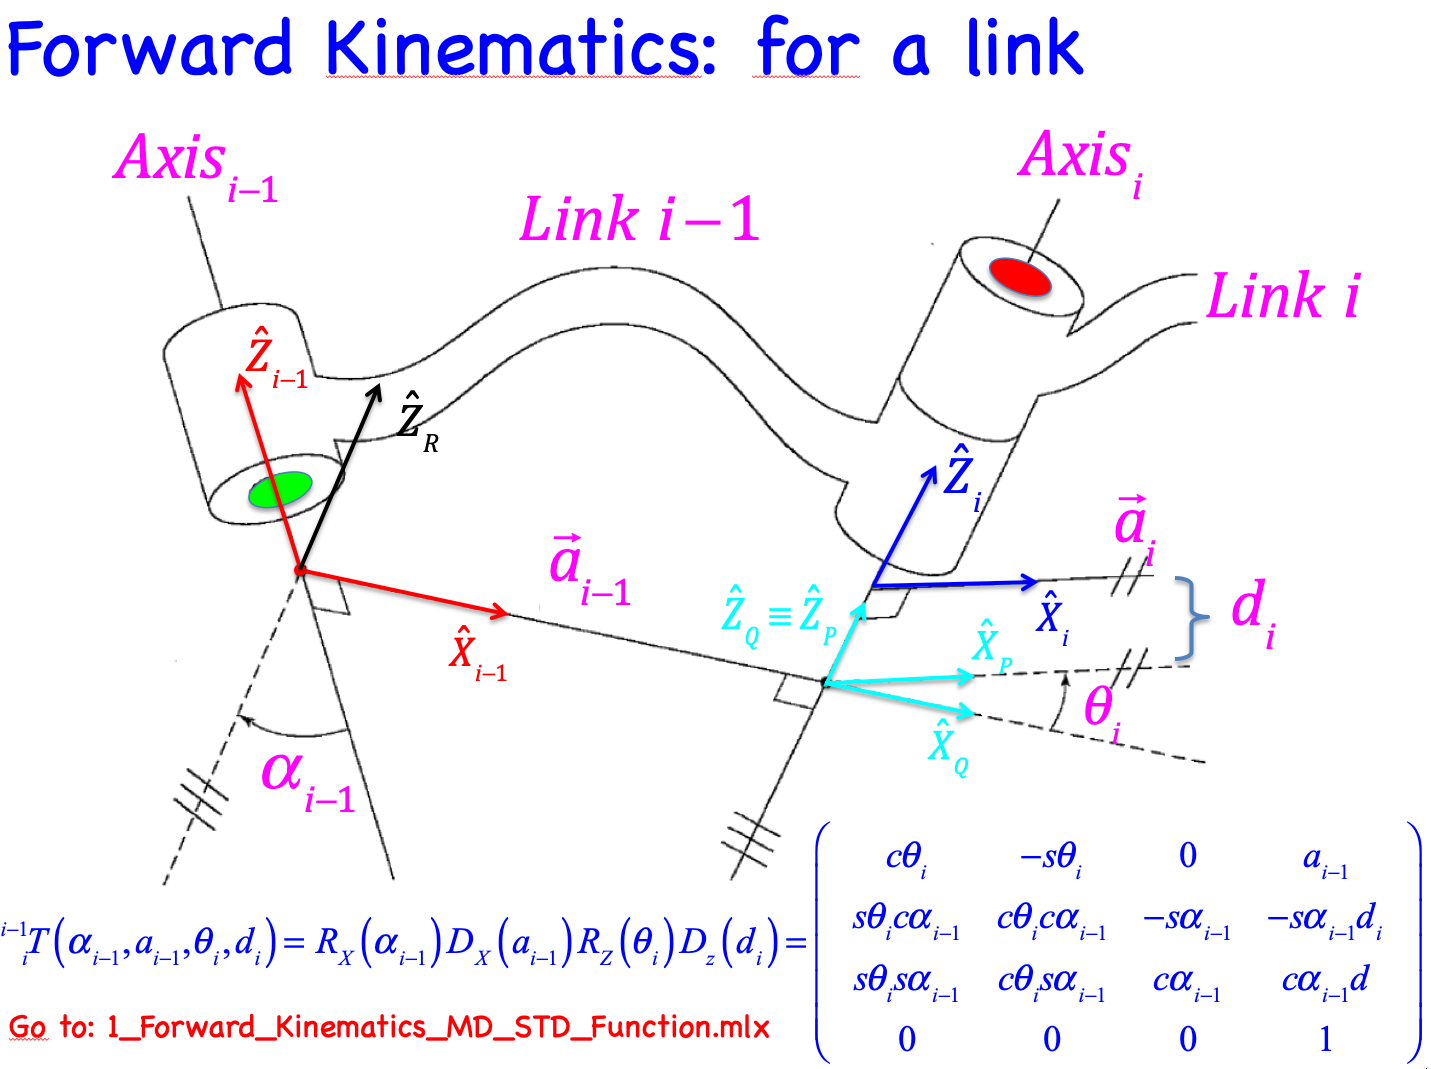

In the symbolic expresion it is used ${\alpha_{i,1} \;\textrm{in}\;\textrm{substitution}\;\textrm{of}\;\alpha }_{i-1} \;\textrm{and}\;\;{a_{i,1} \;\textrm{in}\;\textrm{substitution}\;\textrm{of}\;a}_{i-1}$

clear

As an anonimous function

T_B_A = @(alphai1,ai1,thetai,di)trotx(alphai1)*transl(ai1,0,0)*trotz(thetai)*transl(0,0,di)

T_B_A = function_handle with value:
    @(alphai1,ai1,thetai,di)trotx(alphai1)*transl(ai1,0,0)*trotz(thetai)*transl(0,0,di)


syms alpha_i_1 a_i_1 theta_i  d_i

T_b_a=T_B_A(alpha_i_1,a_i_1,theta_i,d_i)

Unrecognized function or variable 'alphai1'.

syms alpha_i_1 a_i_1 theta_i  d_i
%T_b_a=trotx(alpha_i_1)*transl(a_i_1,0,0)*trotz(theta_i)*transl(0,0,d_i)
%T_b_a=T_b_a(alpha_i_1,a_i_1,theta_i,d_i)

### Chain link connection for Puma 560 Manipulator.

We solve the problem link by link symbolicaly

In fact chain link connection is equivalent to the Forward Kinematics function.

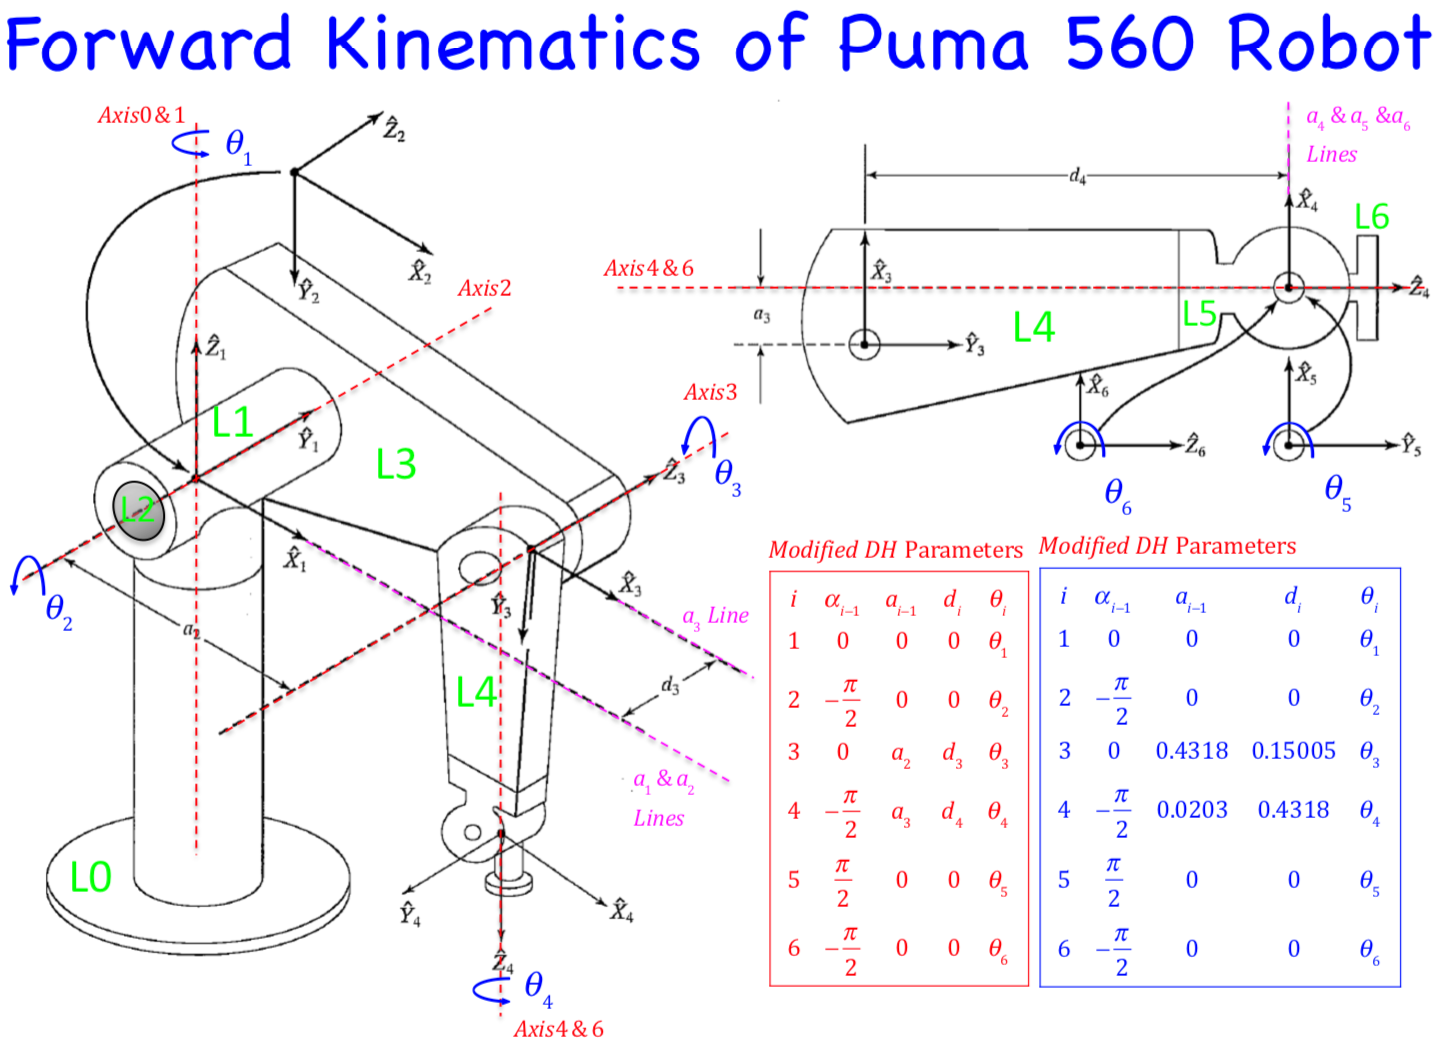

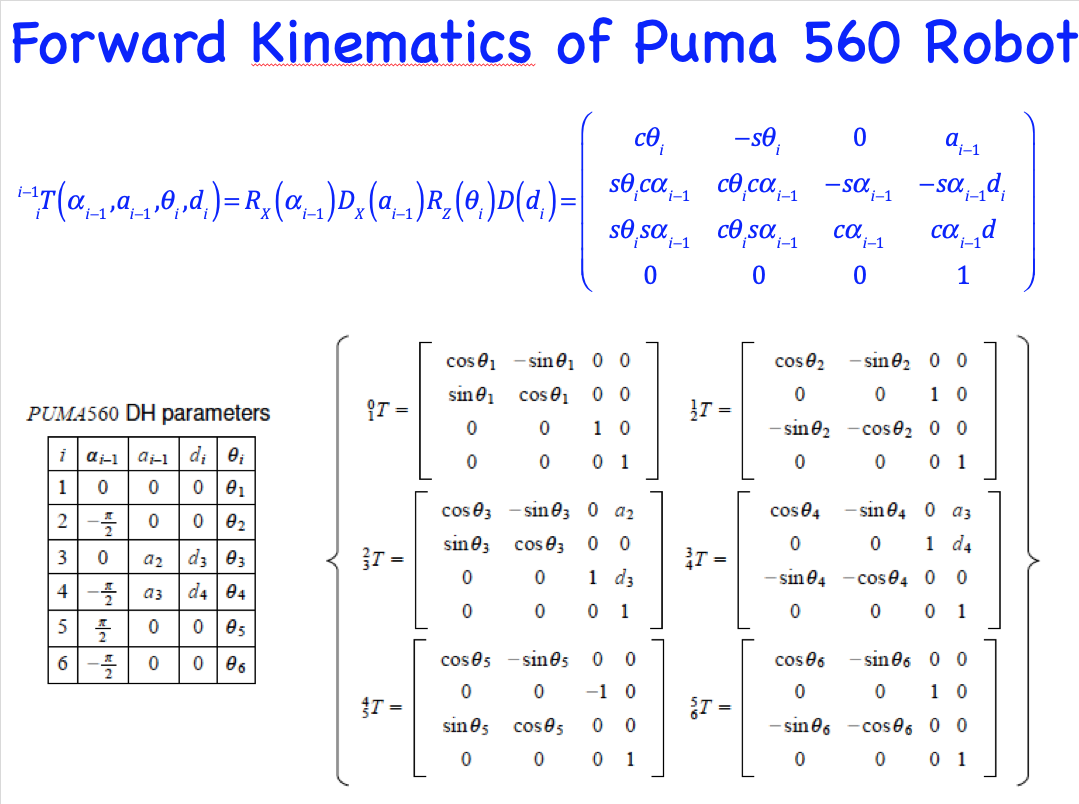

In the symbolic expresion it is used ${\alpha_{i,1} \;\textrm{in}\;\textrm{subtitution}\;\textrm{of}\;\alpha }_{i-1} \;\textrm{and}\;\;{a_{i,1} \;\textrm{in}\;\textrm{subtitution}\;\textrm{of}\;a}_{i-1}$   

syms L1 L2 L3
T1_0=T_B_A(0,0,theta_i,0)

$$T1\_0 = \left(\begin{array}{cccc} \cos\left(\theta_{i}\right) & -\sin\left(\theta_{i}\right) & 0 & 0\\ \sin\left(\theta_{i}\right) & \cos\left(\theta_{i}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T2_1=T_B_A(0, L1+L2, theta_i, 0)

$$T2\_1 = \left(\begin{array}{cccc} \cos\left(\theta_{i}\right) & -\sin\left(\theta_{i}\right) & 0 & L_{1}+L_{2}\\ \sin\left(\theta_{i}\right) & \cos\left(\theta_{i}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T3_2=T_B_A(-pi/2, 0, theta_i, 0)

$$T3\_2 = \left(\begin{array}{cccc} \cos\left(\theta_{i}\right) & -\sin\left(\theta_{i}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ -\sin\left(\theta_{i}\right) & -\cos\left(\theta_{i}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T4_3=T_B_A(0, 0, theta_i, L3)

$$T4\_3 = \left(\begin{array}{cccc} \cos\left(\theta_{i}\right) & -\sin\left(\theta_{i}\right) & 0 & 0\\ \sin\left(\theta_{i}\right) & \cos\left(\theta_{i}\right) & 0 & 0\\ 0 & 0 & 1 & L_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Fordward Kinematics by hand

We create a function for Link description: link_A_B_Md(alpha_i-1, a_i-1, d, theta.)

We test fkine_hand function putting all the qz joint vector at home, i.e. all theta = 0

T_1_0=T_B_A(0,0,0,0)

T_1_0 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


T_2_1=T_B_A(0,0,7,0)

T_2_1 =     0.7539   -0.6570         0         0
    0.6570    0.7539         0         0
         0         0    1.0000         0
         0         0         0    1.0000


T_3_2=T_B_A(-pi/2,0,0,0)

T_3_2 =      1     0     0     0
     0     0     1     0
     0    -1     0     0
     0     0     0     1


T_4_3=T_B_A(0, 2,0,0)

T_4_3 =      1     0     0     2
     0     1     0     0
     0     0     1     0
     0     0     0     1


T_4_0 = T_1_0*T_2_1*T_3_2*T_4_3

T_4_0 =     0.7539         0   -0.6570    1.5078
    0.6570         0    0.7539    1.3140
         0   -1.0000         0         0
         0         0         0    1.0000


T_EE_hand_made=T_4_0

T_EE_hand_made =     0.7539         0   -0.6570    1.5078
    0.6570         0    0.7539    1.3140
         0   -1.0000         0         0
         0         0         0    1.0000


Position=transl(T_EE_hand_made)

Position =     1.5078
    1.3140
         0


Orientation=tr2rpy(T_EE_hand_made)

Orientation =    -1.5708         0    0.7168


T_1_0=link_A_B_Md(0,0,0,0)

T_1_0 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


T_2_1=link_A_B_Md(0,0,7,0)

T_2_1 =      1     0     0     0
     0     1     0     0
     0     0     1     7
     0     0     0     1


T_3_2=link_A_B_Md(-pi/2,0,0,0)

T_3_2 =      1     0     0     0
     0     0     1     0
     0    -1     0     0
     0     0     0     1


T_4_3=link_A_B_Md(0, 2,0,0)

T_4_3 =      1     0     0     2
     0     1     0     0
     0     0     1     0
     0     0     0     1


T_4_0 = T_1_0*T_2_1*T_3_2*T_4_3

T_4_0 =      1     0     0     2
     0     0     1     0
     0    -1     0     7
     0     0     0     1



T_EE_hand_made=T_4_0

T_EE_hand_made =      1     0     0     2
     0     0     1     0
     0    -1     0     7
     0     0     0     1


Position=transl(T_EE_hand_made)

Position =      2
     0
     7


Orientation=tr2rpy(T_EE_hand_made)

Orientation =    -1.5708         0         0


### Building a Robot Manipulator object

See: 'mdl_puma560_Craigh.m' object constructor

clear 
mdl_puma560_Craigh

### Modified DH Table

p560Craigh

 
p560Craigh = 
 
Puma560-Craigh [Unimation]:: 4 axis, RRRR, modDH, slowRNE        
 - Craigh;                                                       
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|          0|          0|
|  2|         q2|          7|          0|          0|          0|
|  3|         q3|          0|          0|     1.5708|          0|
|  4|         q4|          0|          2|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


### 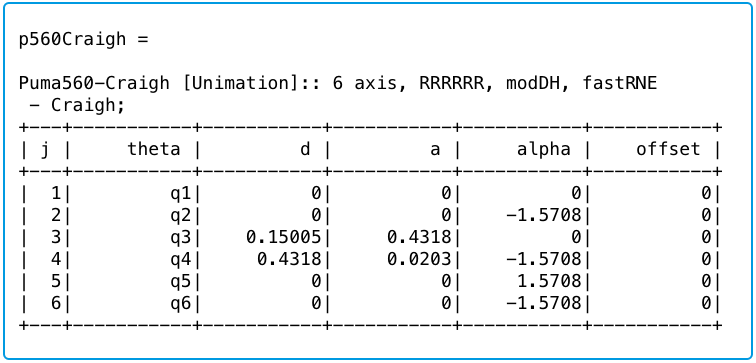

### Animating / Visualizing the chain link connection

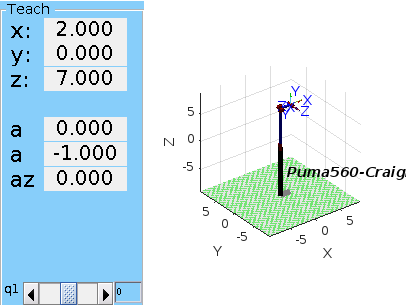

p560Craigh.plot(qz,'zoom',1.5)
hold on
%trplot(T_1_0,'length',0.5,'arrow','width', 0.5,'color','black',...
%             'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})
p560Craigh.teach('approach')

**The Chain**

#### 
$${}_6^0T = {}_1^0T{}_2^1T{}_3^2T{}_4^3T{}_5^4T{}_6^5T$$


#### T_2_0

T_2_0=T_1_0*T_2_1

T_2_0 =      1     0     0     0
     0     1     0     0
     0     0     1     7
     0     0     0     1


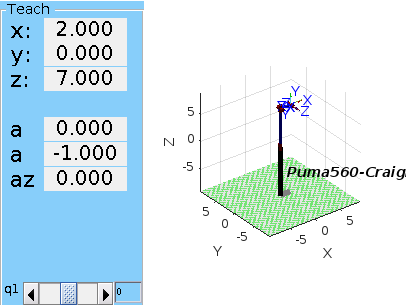

tranimate(T_1_0,T_2_0,20)

#### T_3_0

T_3_0=T_2_0*T_3_2

T_3_0 =      1     0     0     0
     0     0     1     0
     0    -1     0     7
     0     0     0     1


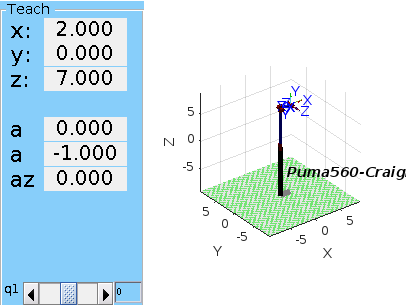

tranimate(T_2_0,T_3_0,20)

#### T_4_0

T_4_0=T_3_0*T_4_3

T_4_0 =      1     0     0     2
     0     0     1     0
     0    -1     0     7
     0     0     0     1


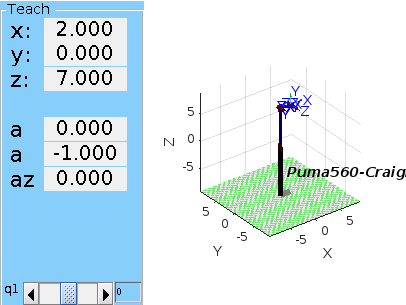

tranimate(T_3_0,T_4_0,20,'length',0.5)

### Fordward Kinematics using RTB 'fkine' 

mdl_puma560_Craigh
T_EE_RTB=p560Craigh.fkine(qz)

 

T_EE_RTB = 
         1         0         0         2
         0         0        -1         0
         0         1         0         7
         0         0         0         1


p560Craigh.plot(qz,'zoom',1.5)

### Comparing result Hand vs RTB

T_EE_hand_made=T_4_0

T_EE_hand_made =      1     0     0     2
     0     0     1     0
     0    -1     0     7
     0     0     0     1


T_EE_RTB

 

T_EE_RTB = 
         1         0         0         2
         0         0        -1         0
         0         1         0         7
         0         0         0         1


Using the RTB puma modified-

Notice it use diferent values for the paramenters

mdl_puma560akb
p560m

 
p560m = 
 
Puma560-AKB [Unimation]:: 6 axis, RRRRRR, modDH, slowRNE         
 - AK&B;                                                         
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|          0|          0|
|  2|         q2|     0.2435|          0|    -1.5708|          0|
|  3|         q3|    -0.0934|     0.4318|          0|          0|
|  4|         q4|     0.4331|    -0.0203|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|     1.5708|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


T_EE_RTBm=p560m.fkine(qz)

 

T_EE_RTBm = 
         1         0         0    0.4115
         0         1         0    0.1501
         0         0         1    0.4331
         0         0         0         1


## Standard DH Parameters.

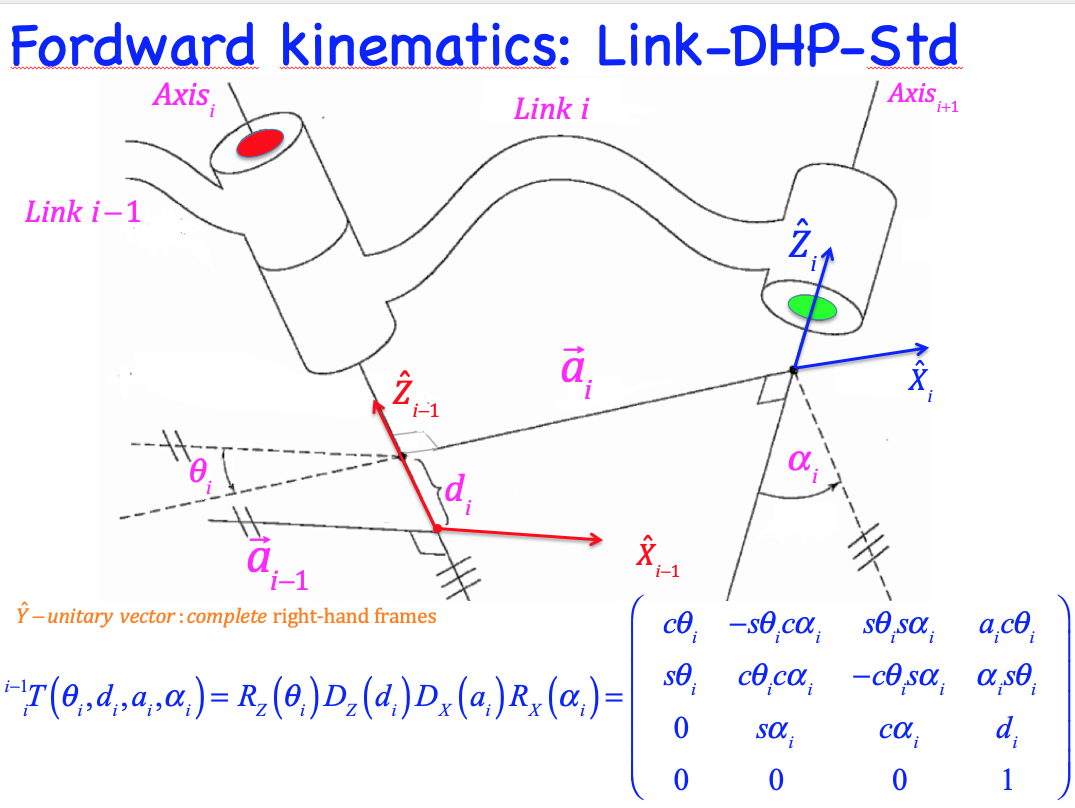

syms alpha_i a_i theta_i  d_i 
T_b_a=trotz(theta_i)*transl(0,0,d_i)*transl(a_i,0,0)*trotx(alpha_i)
T_b_a_mod=trotx(alpha_i_1)*transl(a_i_1,0,0)*trotz(theta_i)*transl(0,0,d_i)

### Standard DH table

The input parameter order into the function is: alpha, a, d, theta.

We test the qz joint vector. all theta = 0

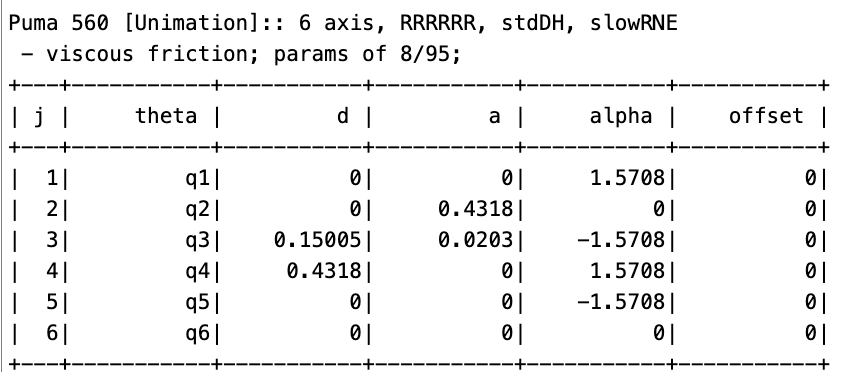

### 'fkine' by hand

The function need (alpha,a,d,theta)

The link chain 

clear
T_1_0=link_A_B_Std(0,0,0,0)

T_1_0 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


T_2_1=link_A_B_Std(0,0,7,0)

T_2_1 =      1     0     0     0
     0     1     0     0
     0     0     1     7
     0     0     0     1


T_3_2=link_A_B_Std(-pi/2,0,0,0)

T_3_2 =      1     0     0     0
     0     0     1     0
     0    -1     0     0
     0     0     0     1


T_4_3=link_A_B_Std(0, 2,0,0)

T_4_3 =      1     0     0     2
     0     1     0     0
     0     0     1     0
     0     0     0     1


T_4_0 = T_1_0*T_2_1*T_3_2*T_4_3

T_4_0 =      1     0     0     2
     0     0     1     0
     0    -1     0     7
     0     0     0     1



T_EE_hand_made=T_4_0

T_EE_hand_made =      1     0     0     2
     0     0     1     0
     0    -1     0     7
     0     0     0     1



Position=transl(T_EE_hand_made)

Position =      2
     0
     7


Orientation=tr2rpy(T_EE_hand_made)

Orientation =    -1.5708         0         0


### Comparing results hand vs RTB

mdl_puma560
%T_EE_RTB=p560.fkine(qz)
T_EE_hand_made=p560.fkine(qz)

 

T_EE_hand_made = 
         1         0         0    0.4521
         0         1         0     -0.15
         0         0         1    0.4318
         0         0         0         1


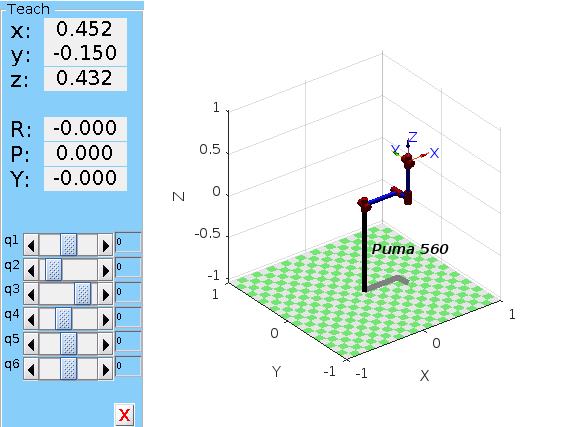

p560.plot(qz,'zoom',1.5)
p560.teach

## Wrist orientation

Play with the teach and visit: help tr2rpy RTB function.

q_teach= [1 1 1 1 1 1]*45*pi/180
T_EE_RTB=p560.fkine(q_teach) % Robot pose with all joins at 45 degrees
Wrist_o=tr2rpy(T_EE_RTB.T,'arm')*180/pi

## Functions in the mlx

Put at the end all specific function that clarify the code.

function T_b_a=link_A_B_Md(alpha,a,d,theta)
T_b_a=trotx(alpha)*transl(a,0,0)*trotz(theta)*transl(0,0,d);
end

function T_b_a=link_A_B_Std(alpha,a,d,theta)
T_b_a=trotz(theta)*transl(0,0,d)*transl(a,0,0)*trotx(alpha);
end